# Time lapsed tSNE plots of syllables

## STEP 1:  Set criteria for getting syllable spectrograms

### A - Change configuration settings for syllabe inclusion criteria and spectrogram settings.

Manually change settings in the section below

% Query for syllables to be retrieved
birdname = 'br177yw112';
days_folder_id = [62,661,662,68,73,86,88];%[78 801 802 803 811 153] [62,661,662,68,73,86,88];
syls = ['bcdgkrmhj']; % 'all' or syllable labels
min_max_duration = [30 150]; % select syls only with this min and max duration in milliseconds

% Set spectrogram parameters
overlap_windowsize = [0.5 8]; % spectrogram windows: pct overlap, bin size (msec)
fixed_tmax = 64; % transform specs into n x n size spectrograms using interpolation function

% Set parent directory for saving output files
parentdir = "C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\tSNE_syllable_spects";
cd(parentdir)

Section below is auto-generated from previous section.

### B - Create sub-directory for saving output files

% Create substrings for directory name and output file name
    dateGenerated = char(datetime("today","Format","uuuu-MMM-dd")); 
    % Convert array of days to a string with underscores between them
    % Change folder name to actual day, age
    days= days_folder_id;
    days(days == 661 | days == 662) = 66;
    days(days == 801 | days ==802 | days ==803) = 80;
    days(days == 811 | days ==812) = 81;
    days = unique(days);
    daysString = strjoin(arrayfun(@(x) num2str(x), days, 'UniformOutput', false), '-'); 

% Concatenate strings for directory and file names
output_folder = sprintf('%s_syls_%s_days_%s_%s',birdname,syls,daysString,dateGenerated(1:11))

output_folder = 'br177yw112_syls_bcdgkrmhj_days_62-66-68-73-86-88_2024-Jun-04'

    if ~exist(output_folder)
            mkdir(output_folder)
    end
savedir = strcat(parentdir,'\',output_folder);
specs_filename = sprintf('spectrograms_%s_syls_%s_days_%s.mat',birdname,syls,daysString)

specs_filename = 'spectrograms_br177yw112_syls_bcdgkrmhj_days_62-66-68-73-86-88.mat'

### C - Create parameter structures for input arguments & saved in output file

params = struct(...
    "birdname", birdname,...
    "days_folder_id",days_folder_id,...
    "days", days,...
    "syls", syls,...
    "min_max_duration",min_max_duration,...
    "overlap_windowsize",overlap_windowsize);

## Step 2: Get spectrograms for desired syllable trials

params = struct with fields:
              birdname: 'br177yw112'
        days_folder_id: [62 661 662 68 73 86 88]
                  days: [62 66 68 73 86 88]
                  syls: 'bcdgkrmhj'
      min_max_duration: [30 150]
    overlap_windowsize: [0.5000 8]


day = 62

min_win_length = 8

max_win_length = 33

ind_min = 21

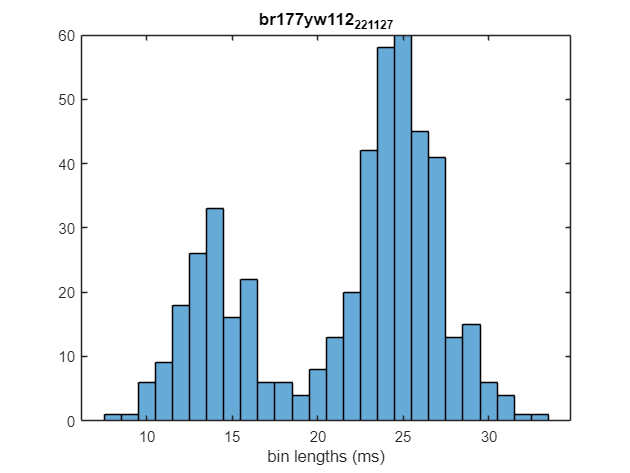

syl_min_win = 'c'

day = 661

min_win_length = 9

max_win_length = 33

ind_min = 57

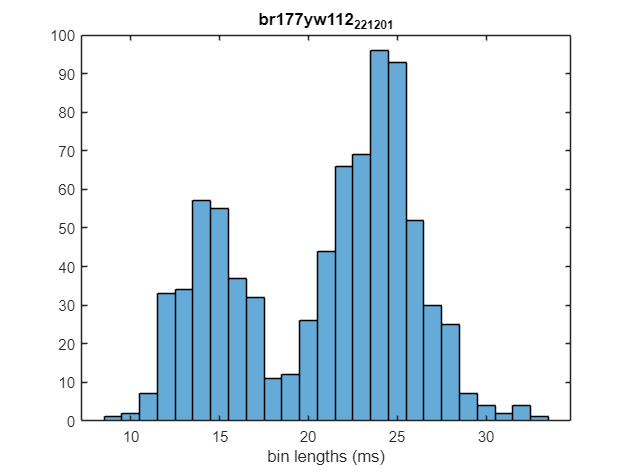

syl_min_win = 'm'

day = 662

min_win_length = 9

max_win_length = 33

ind_min = 57

syl_min_win = 'm'

day = 68

min_win_length = 7

max_win_length = 33

ind_min = 3351

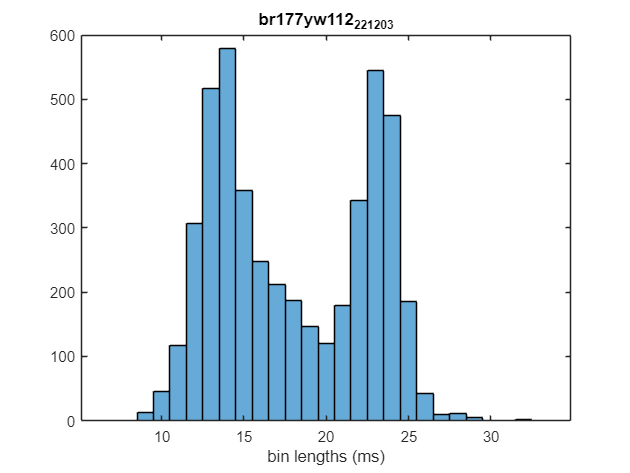

syl_min_win = 'g'

day = 73

min_win_length = 6

max_win_length = 33

ind_min = 3125

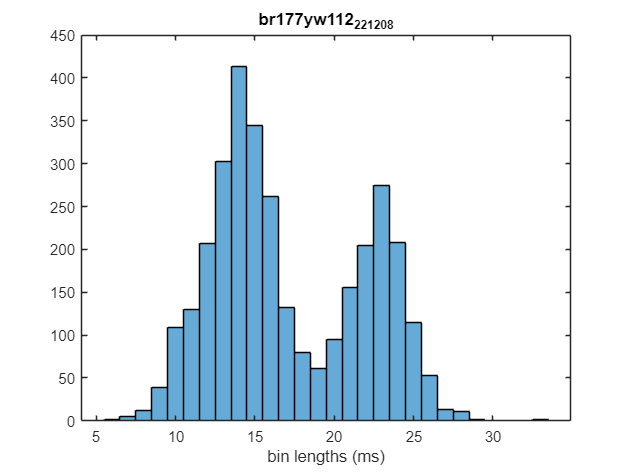

syl_min_win = 'm'

day = 86

min_win_length = 6

max_win_length = 30

ind_min = 66

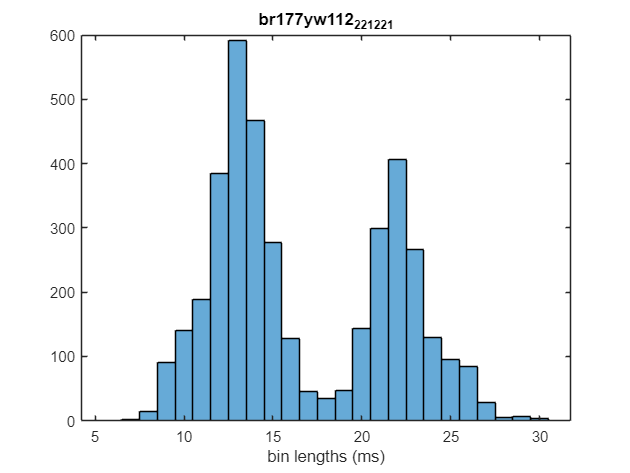

syl_min_win = 'm'

day = 88

min_win_length = 6

max_win_length = 31

ind_min =           47
        3035
        3738


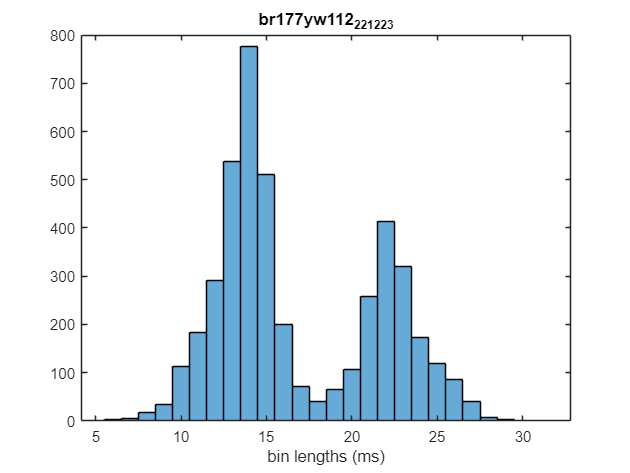

syl_min_win = 'mmm'

warning('off')
getAllSylSpects(savedir,specs_filename,params);

## Step 3: Create spectrogram matrix with fixed desired spectrogram bin length

### A - Choose Settings

- Setting bin length to "shortest" will cut the spectrograms to # of time bins of the shortest syllable

- Setting bin length to "longest" will add zeros to time bins of syllables that are shorter than the longest syllable

- Settin bin length  to "tmax" will fit to tmax-by-tmax size spectrograms using interpolation function

% Retrieve spectrograms
cd(savedir)
filename = specs_filename;
load(filename,'spectrograms_full_syl_durations')

% Set desired bin length
set_bin_length = "fixed"; % set spectrogram length will be to the "shortest" or "longest" syllable or fixed for interpolation

### B - Get spectrogram matrix from above settings and append output file

% Create spect matrix for t-SNE
if set_bin_length == "shortest"
    % Find the number of time bins
    min_time_bins = calcNumBins(spectrograms_full_syl_durations,set_bin_length)
    min_selected_bins = [1 min_time_bins]; % which spectrogram time bins

    % Create Matrix for selected time bins
    spectrograms_binlength_shortest = createSpectMatrix(spectrograms_full_syl_durations,min_selected_bins,set_bin_length);
    save(filename,"spectrograms_binlength_shortest","min_selected_bins",'-append');

elseif set_bin_length == "longest"
    % Find the number of time bins
    max_time_bins = calcNumBins(spectrograms_full_syl_durations,set_bin_length)  
    selected_bins = [1 max_time_bins];
    % Pad empty time bins with zeros for syllables < max duration
    spectrograms_binlength_longest = createSpectMatrix(spectrograms_full_syl_durations,selected_bins_set_bin_length);
    save(filename,"spectrograms_binlength_longest",'-append');

elseif set_bin_length == "fixed"
    spectrograms_binlength_fixed = createSpectMatrix(spectrograms_full_syl_durations,spec_tmax,set_bin_length);
    save(filename,"spectrograms_binlength_fixed","fixed_tmax",'-append');
end

## Step 3: Apply t-SNE to chosen spectrogram matrix

### A - Set t-SNE parameters

% Retrieve which spectrogram matrix
filename = specs_filename;
spec_matrix=struct2array(load(filename,sprintf('spectrograms_binlength_%s',set_bin_length)));
featureMatrix = spec_matrix;

% t-SNE parameters
dimensions = 3; % 2 and/or 3 dimensions
seed = rng(42); % Set random seed for reproducibility
tsne_setting = "default"; % 'default' or 'custom' tsne function settings

% Optional: custom settings
perp = 50; % perplexity: number of local neighbors of each point; increase with increasing datasets
exg = 10; % exaggeration factor: tends to increase distance between clusters

tsne_filename = sprintf('tsne_%s_syls_%s_days_%s_binlength_%s',birdname,syls,daysString,set_bin_length)

tsne_filename = 'tsne_br177yw112_syls_bcdgkrmhj_days_62-66-68-73-86-88_binlength_fixed'


if tsne_setting == "default"
    tsne_params = struct(...
        "setting", tsne_setting,...
        "dimensions", dimensions,...
        "seed", seed)
elseif tsne_setting == "custom"
    tsne_params = struct(...
        "setting",'custom',... % 'default' or 'custom' tsne function settings
        "dimensions",dimensions,...
        "seed", seed,...
        "perplexity", perp,...
        "exaggeration", exg); % Set random seed for reproducibility
end

tsne_params = struct with fields:
       setting: "default"
    dimensions: 3
          seed: [1×1 struct]


### B - Apply t-SNE

eval("rng(seed.Seed)") % Set random seed for reproducibility
if tsne_setting == "custom"
    [tsneResult,loss] = tsne(featureMatrix, 'NumDimensions', dimensions,'Perplexity',perp,'Exaggeration',exg);
    disp(loss)
else
    [tsneResult,loss] = tsne(featureMatrix,'NumDimensions',dimensions)
end

tsneResult =    14.5597   -3.8648    1.2802
  -30.9176   -9.4778    6.0063
   -1.5042   34.8118   46.1035
   18.5642   -4.2997    2.4851
  -33.6688  -11.7729    5.5883
  -30.2416  -10.2779    5.5026
   -2.5750   31.0769   47.5406
   18.5415   -7.4116    5.7078
  -33.4387  -13.0526    5.5622
  -26.7331  -29.5760   -4.9309


loss = 1.5056

% Save to existing file
eval(sprintf('tsneResult_%dD_perp%d_exg%d = tsneResult;',dimensions,perp,exg));
if exist([tsne_filename '.mat'])
    save(tsne_filename,sprintf('tsneResult_%dD_perp%d_exg%d',dimensions,perp,exg),'-append')
else
    save(tsne_filename,sprintf('tsneResult_%dD_perp%d_exg%d',dimensions,perp,exg))
end

## Step 4: Plot t-SNE results

### Static Plot

plot_dimensions = 2;
% Load days and syllable labels for each trial
days_all=struct2array(load(specs_filename,'days_all'));
labels_all=struct2array(load(specs_filename,'labels_all'));
colorBy = 'syllable'; % scatter plot color by 'syllable' or 'days'

% only plot some syllables
chars_to_find = 'bk';

% Finding indices
indices = find(ismember(labels_all, chars_to_find));

% Find the indices where any of the characters are present
days_select = days_all(indices);
labels_select = labels_all(indices);
tsne_selectsyls = tsneResult(indices,:);

% Plot tSNE
plotTsne(tsne_selectsyls,plot_dimensions,days_select,labels_select,colorBy)

Unrecognized function or variable 'daysLabels'.

Error in plotTsne>assignColors (line 51)
    daysNorm = (daysLabels - min(daysLabels)) / (max(daysLabels) - min(daysLabels));

Error in plotTsne (line 19)
    labelColors = assignColors(labelsToColor, uniqueLabels);

title(filename,'Interpreter','latex')
subtitle(sprintf('Perplexity =%d, Exaggeration = %d', perp, exg))

% Save figure
savefig(gcf,strcat(tsne_filename,sprintf('_%dD_perp%d_exg%d.fig',plot_dimensions,perp,exg)))

### Create video of tSNE results plotted through a sliding window

% Define the tSNE on the whole dataset
tsneResultAll = tsneResult;

% Fix the xyz axes based on the max values of the tsne results
ax_mins = [min(tsneResultAll(:, 1)), min(tsneResultAll(:, 2)), min(tsneResultAll(:, 3))];
ax_maxes = [max(tsneResultAll(:, 1)), max(tsneResultAll(:, 2)), max(tsneResultAll(:, 3))];

% Define parameters
bin_width = 1000;
bin_step = 50;

% Create a VideoWriter object
video_filename = [tsne_filename(1:end-4), '_MOVIE_bw' num2str(bin_width) '_step' num2str(bin_step) '.avi'];
video_writer = VideoWriter(video_filename);
video_writer.FrameRate = 5;

% Extract the base name for the directory
[folderPath, baseFileName, ~] = fileparts(video_filename);
newDir = fullfile(folderPath, baseFileName);
if ~exist(newDir)
    mkdir(newDir); % Create the new directory
end
cd(newDir)

open(video_writer);


% Assign fixed colors for all labels 
uniqueLabels = unique(labels_all);
numUniqueLabels = numel(uniqueLabels);
load('colorAlphabet.mat', 'colorAlphabet'); % Load the colormap from the .mat file
colors = colorAlphabet(1:numUniqueLabels,:); % You can use any colormap you prefer

% Create a color map based on labels
labelColors = zeros(length(labels_all), 3);
for i = 1:numUniqueLabels
    labelColors(labels_all == uniqueLabels(i), :) = repmat(colors(i, :), sum(labels_all == uniqueLabels(i)), 1);
end


figure;

for start_row = 1:bin_step:(size(tsneResult, 1) - bin_width + 1)
    end_row = start_row + bin_width - 1;
    
    % Extract the current window and labels
    tsneResult_bin = tsneResultAll(start_row:end_row, :);
    plotLabels_bin = labels_all(start_row:end_row);
    uniqueLabels_bin = unique(plotLabels_bin);
    numUniqueLabels_bin = numel(uniqueLabels_bin);
    labelColors_bin = labelColors(start_row:end_row,:);

    % Create 3D scatter plot
    hold on;
    for i = 1:numUniqueLabels_bin
        idx = plotLabels_bin == uniqueLabels_bin(i);
        scatter3(tsneResult_bin(idx, 1), tsneResult_bin(idx, 2), tsneResult_bin(idx, 3), 3, labelColors_bin(idx, :), 'filled');
        
        % Label each cluster with the associated character
        centroid = mean(tsneResult_bin(idx, :), 1);
        text_color = labelColors_bin(find(idx, 1), :);
        text(centroid(1), centroid(2), centroid(3), uniqueLabels_bin(i), 'FontSize', 15, 'FontWeight', 'bold', 'Color', text_color);
    end
    hold off;

    % Set the axes limits
    xlim([ax_mins(1) ax_maxes(1)]);
    ylim([ax_mins(2) ax_maxes(2)]);
    zlim([ax_mins(3) ax_maxes(3)]);

    % Additional formatting
    title(['br177yw112']); % Adjust title as needed
    xlabel('t-SNE1');
    ylabel('t-SNE2');
    zlabel('t-SNE3');
    view(3); % Set the view to 3D
   

    % Pause for a short duration to create the animation effect
    pause(0.1);

    % Save the figure in .fig format only every 1000 trials
    if mod(start_row, 1000) == 1
        set(gcf,'Visible','On')
        figureFilename = sprintf('tSNE_perp%d_exg%d_%d.fig', perp,exg,start_row);
        savefig(gcf, figureFilename);
    end

    % Capture the current frame for the movie
    frame = getframe(gcf);
    writeVideo(video_writer, frame);

    % Clear the current figure for the next iteration
    clf;
end

% Close the video writer
close(video_writer);
cd ..